# **ThermOptCC**

ThermOptCC (TOCC) is an algorithm that identifies blocked reactions in a metabolic model, considering both stoichiometric and thermodynamic constraints. Blocked reactions are those that cannot carry flux under any feasible condition, and their presence can indicate gaps or inconsistencies in the model. TOCC goes beyond traditional flux consistency checks by identifying reactions that are blocked specifically due to thermodynamic infeasibility. This allows for a more comprehensive assessment of model quality and can guide targeted improvements. TOCC requires a GEM and the corresponding TICs (identified by TOE) as inputs. It outputs a classification of all reactions in the model, categorizing them as Forward, Reverse, Reversible, or Blocked based on their thermodynamic and stoichiometric feasibility. This tutorial shows a demo of implementation of ThermOptCC to obtain the feasible flux directions and also to get the reactions that are blocked because of stochiometric constraints (dead-end metabolites) and because of thermodyncamic constraints.

**Reading the COBRA model (The model should have the following fields: S, lb, ub, rxns)**

fileName = 'iAF1260.mat';
model = readCbModel(fileName);

Each model.subSystems{x} is a character array, and this format is retained.


**Obtaining the feasible flux directions for the metabolic model**

tol = 1e-5;
[a,TICs,Dir,modModel,TIC_Rxns] = ThermOptCC(model,tol);

'a' contains the details of thermodynamically feasible flux directions in the metabolic model "modModel". "modModel" is same as "model" except that all the irreversible reactions in reverse direction are converted to forward direction reactions. The outputs TICs, Dir, modModel,TIC_Rxns are returned by ThermOptEnumerator that is used internally in ThermOptCC.

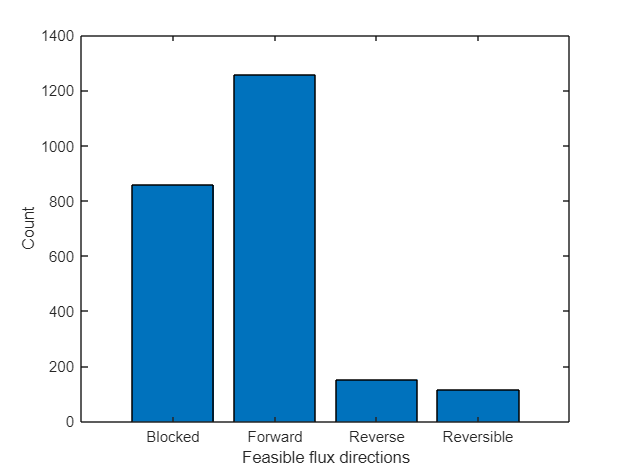

% getting the count of unique values of the feasible flux directions
unique_a = unique(a);
count = cellfun(@(x)sum(strcmp(a,x)),unique_a);
bar(unique_a,count)
xlabel('Feasible flux directions')
ylabel('Count')

To get the reactions that are blocked because of thermodynamic constraints alone, we first need to obtain the reactions that are blocked because of stoichiometric constriants

all_blkd_ids = find(ismember(a,'Blocked')); % list of all the blocked reactions ids
fc_ = fastcc(model,tol,0); 
stoi_blkd = setdiff([1:numel(model.rxns)],fc_); % list of all the reaction ids that are stoichiometrically blocked
therm_blkd = setdiff(all_blkd_ids,stoi_blkd); % list of all the reaction ids that are thermodynamically blocked

n_therm_blkd = numel(therm_blkd); % count of number of reactions that are thermodynamically blocked
n_stoi_blkd = numel(stoi_blkd); % count of number of reactions that are stoichiometrically blocked

The stoichiometrically blocked reactions can change based on the given input media conditions (given as bounds to exchange reactions) but, thermodynamically blocked reactions always remain the same irrespective of the given input media conditions.